clear; clc;

%% 설정
csv_path = 'D:\W00Y0NG\PRGM2\2025BCI\current_experiments\DATA\raw\experiment_001\(2).csv';
epoch_table_path = 'D:\W00Y0NG\PRGM2\2025BCI\current_experiments\DATA\video\experiment_001_epochs.xlsx';
loc_path = 'D:\W00Y0NG\PRGM2\MATLAB\eeglab2024.2\sample_locs\Standard-10-20-Cap81.ced';

save_filename = 'experiment_001(2)';
save_dir = 'D:\W00Y0NG\PRGM2\2025BCI\current_experiments\DATA\processed\';

fs = 125;

selected_labels = {'FP1','FP2','C3','C4','P7','P8','O1','O2', ...
                   'F7','F8','F3','F4','T7','T8','P3','P4'};

%% CSV + 자극 -> epoch 데이터 생성
[epochedEEG, labels] = epochEEGfromCSV(csv_path, epoch_table_path, fs, 10);


%% epoch 데이터 -> EEGLAB EEG 구조체
EEG = createEEGLABStruct(epochedEEG, labels, fs, loc_path, selected_labels, '');

Reading file (lines): 10 20 30 40 50 60 70 80 81
readlocs() warning: Fewer columns in the input than expected.
                    See >> help readlocs



%% EEG 구조체 -> 전처리 클래스 생성
p = EEGPreprocessor(EEG, labels, EEG.chanlocs);

%% 전처리 단계 실행
p = p.applyBandpass(0.5, 40);

Bandpass filtering complete.


p = p.applyNotch(60);

Notch filtering complete.


p = p.runICA();


Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (15) is smaller than the number of channels (16).

Input data size [15,90000] = 15 channels, 90000 frames/nAfter PCA dimension reduction,
  finding 15 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 400 frames per ICA weight ((225)^2 = 90000 weights, Initial learning rate will be 0.001, block size 58.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -5.0034 to 5.35513
Reducing the data to 15 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step 1 

p = p.runADJUST();

 
Features Extraction:
GDSF - General Discontinuity Spatial Feature...
SED - Spatial Eye Difference...
SAD - Spatial Average Difference...
Temporal Kurtosis...
Maximum epoch variance...
Computing EM thresholds...
 
Artifact Identification:
Horizontal Eye Movements...
Vertical Eye Movements...
Eye Blinks...
Generic Discontinuities...
 
Results in <D:\W00Y0NG\PRGM2\2025BCI\current_experiments\CODE\1_preprocessing\ADJUST_Report_20250508_183827.txt>.


Drawing figure...


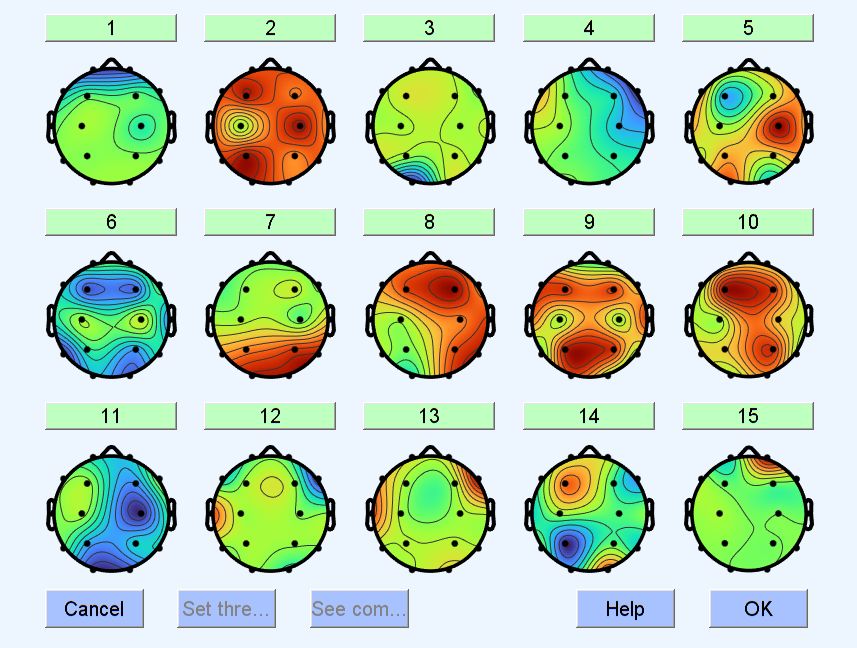

Computing projection and removing 7 components ....
Remove Components complete.



%% ICA 컴포넌트 수동 제거
p = p.removeComponents();


%% 재참조 및 저장
p = p.rereference();

Re-referencing data
Re-referencing ICA matrix
Scaling components to RMS microvolt
Re-referencing complete.



% EEG 저장
EEG_clean = p.getEEG();
labels = cellstr(labels);
save(fullfile(save_dir, [save_filename, '_cleaned.mat']), 'EEG_clean', '-v7.3');
writecell(labels', fullfile(save_dir, [save_filename, '_labels.csv']));

disp('전처리 완료');

전처리 완료
